# January 20th 2020, MPC Homework One

% Author: Lucky Yerimah
clc; clear all % clearing all previous variables
% Three Tank Data
A = [-1, 0, 0; 1, -1, 0; 0, 1, -1];
B = [1;0;0];
C = [0,0,1];
D = 0;

## Problem One

eig(A) % eigen values of Matrix A

ans =     -1
    -1
    -1


% unit of eigenvalues is per minute (1/min)


## Problem Two

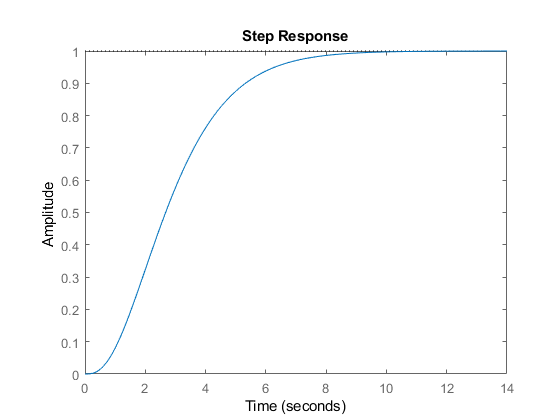

sys = ss(A,B,C,D); % creating continuous-time state space model
step(sys) % unit step change

## Problem Three

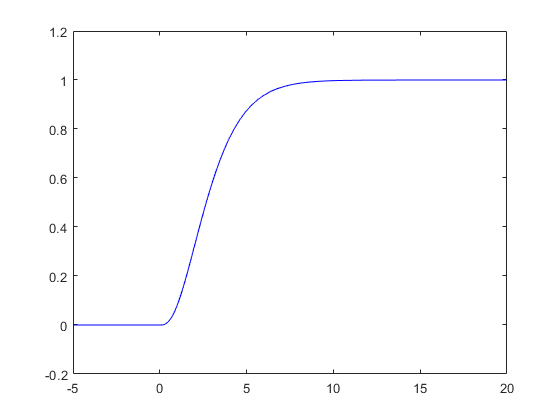

tbeg = -5; % initial time in minutes
tend = 20; % final time in minutes
x0 = [0,0,0]; % initial conditions
[t,x] = ode45(@example3tank,[tbeg tend], x0); % ODE45 function
figure (1)
plot(t,x(:,3), 'b'); % plot output

## Problem Four

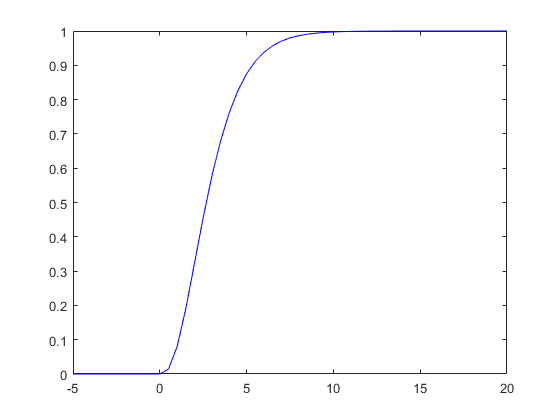

time = (-5:0.5:20); % time vector in minutes
x0 = [0,0,0]; % initial conditions
for k = 1:length(time)-1; % step change at time = 0
    if time(k) < 0;
        u(k) = 0;
    else 
        u(k) = 1;
    end
end
xdot(:,1) = x0; % initial state condition
% generating a new time vector (tnew) and array of the states (xnew) for
% each time interval t(k) and t(k+1)
for k = 1:length(time)-1;
[tnew,xnew] = ode45(@example4tank,[time(k) time(k+1)], xdot(:,k),[],u(k)); % ODE45 function
ntime = length(tnew); % computes the length of tnew
xdot(:,k+1) = xnew(ntime,:)'; % orienting xnew to the state columns
% line 34 and 35 can be written as simply xdot(:,k+1) = xnew(end,:)
end
u(k+1) = u(k); % making the input change to same as the time vector
figure (3)
plot(time,xdot(3,:), "B") 

## Problem Five

[Num, Dem] = ss2tf(A,B,C,D) % Converting state space to transfer function

Num =      0     0     0     1


Dem =      1     3     3     1


sys2 = tf(Num, Dem)


sys2 =
 
            1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.



P = pole(sys2) % Poles of the transfer function

P =   -1.0000 + 0.0000i
  -1.0000 - 0.0000i
  -1.0000 + 0.0000i


% Poles of tranfer function is the same as the eigen values of the A matrix
% 

function xdot = example3tank(t,x)
if t<0
    u = 0; %input step change at t = 0
else 
    u = 1; % input step change at t = 0
end
% State space equations 
xdot(1) = -x(1) + u;
xdot(2) = x(1) - x(2);
xdot(3) = x(2) - x(3);

xdot = xdot'; % converting the ODEs to column vector

end

function xdot = example4tank(t,x,flag,u)
if t<0
    u = 0; %input step change at t = 0
else 
    u = 1; % input step change at t = 0
end
% State space equations 
xdot(1) = -x(1) + u;
xdot(2) = x(1) - x(2);
xdot(3) = x(2) - x(3);

xdot = xdot'; % converting the ODEs to column vector

end